# **KUKA  Iiwa 7 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Clear the environment.

clc;
clear;
close all;

Load the KUKA Iiwa 7 rigid body tree (RBT) model.

robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "iiwa_link_ee_kuka"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.7 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

close all;
%% Construct voxel obstacle representation for STOMP planner
% Define the workspace (the voxel world limits). Depending on the robot's reach range.
Env_size = [-1, -1, -1; 2, 2, 2];  % [xmin, ymin, zmin] for 1st row, xyz-lengths for 2nd row
voxel_size = [0.02, 0.02, 0.02];  % unit: m
% Binary map: all free space initially, 
binary_world = zeros(Env_size(2, 1) / voxel_size(1), Env_size(2, 2) / voxel_size(2), Env_size(2, 3) / voxel_size(3));
% binary_world_offset = Env_size(1, :)./ voxel_size;

%% XYZ metric representation (in meter) for each voxel 
% !!!!Watch out for the useage of meshgrid:
% [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the 
% vectors x, y, and z. The grid represented by X, Y, and Z has size 
% length(y)-by-length(x)-by-length(z).
% The 3D coordinate is of the center of the voxels
[Xw, Yw, Zw] = meshgrid(Env_size(1, 1) + 0.5 * voxel_size(1) : voxel_size(1) : Env_size(1, 1) + Env_size(2, 1) - 0.5 * voxel_size(1), ...
       Env_size(1, 2) + 0.5 * voxel_size(2) : voxel_size(2) : Env_size(1, 2) + Env_size(2, 2) - 0.5 * voxel_size(2), ...
    Env_size(1, 3) + 0.5 * voxel_size(3) : voxel_size(3) : Env_size(1, 3) + Env_size(2, 3) - 0.5 * voxel_size(3));

world = {};
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.6]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.8]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.4 0.5 0.6]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.4 0.5 0.8]);

volumeViewer(binary_world);

%% construct signed Euclidean Distance for the voxel world
% Only approximation if the voxel is not a cube
voxel_world_sEDT = prod(voxel_size) ^ (1/3) * sEDT_3d(binary_world);


voxel_world.voxel_size = voxel_size;
voxel_world.voxel = binary_world;
% voxel_world.offset =  binary_world_offset;
voxel_world.world_size = size(binary_world);
voxel_world.Env_size = Env_size; % in metric 
voxel_world.sEDT =  voxel_world_sEDT;


Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

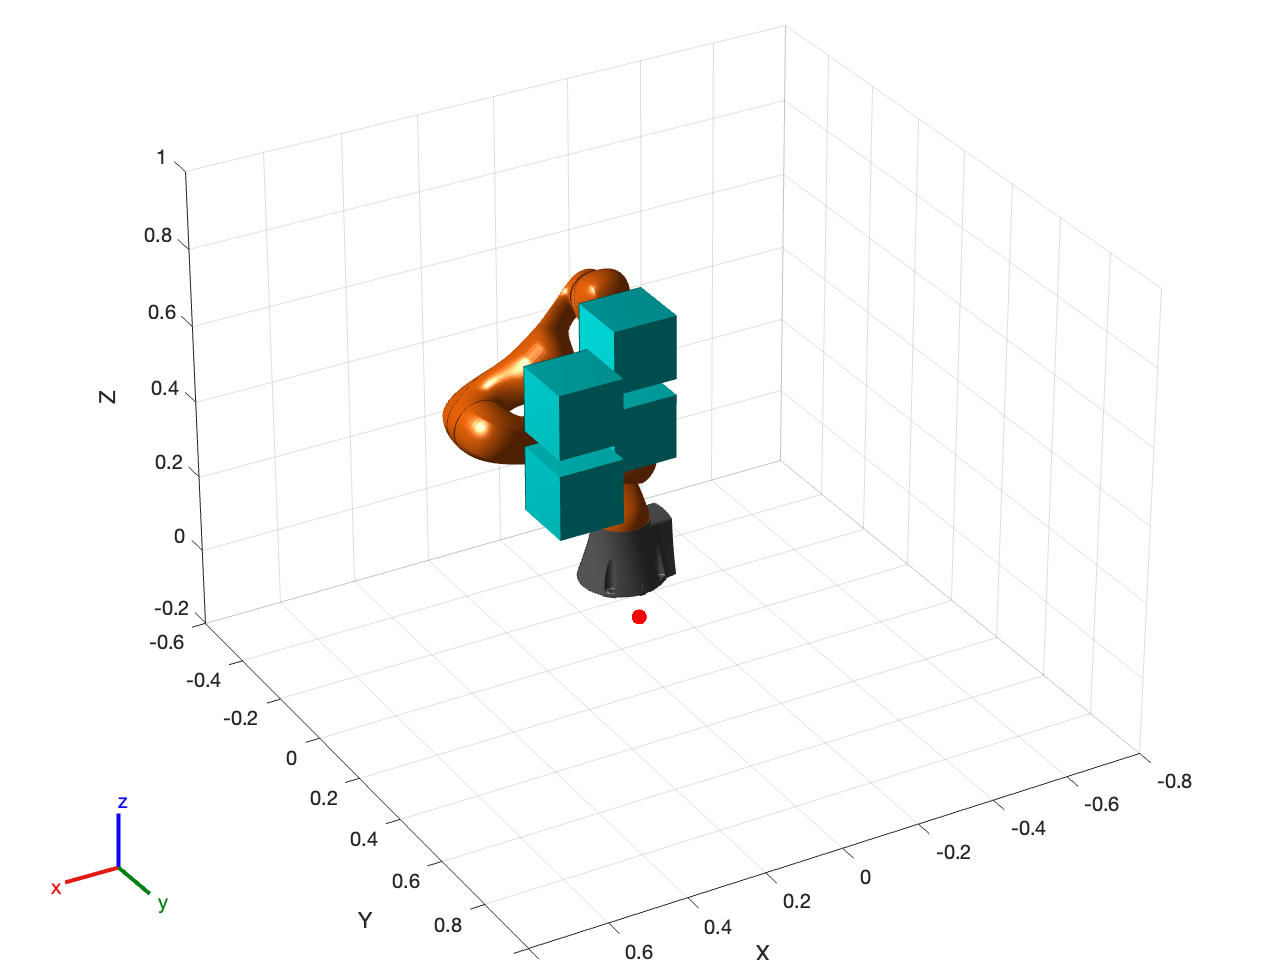

x0 = [currentRobotJConfig', zeros(1,numJoints)];

% Visualize the obstacles and robot manipulator

% Initial visualizer
positions = x0(1:numJoints)';

% figure(): The 1st and 2nd number is the pixel position of the figure relative to
% the monitor display. The 3rd and 4th number are the width and height of
% the figure.
hgif = figure('Position', [375 446 641 480]);
% 'PreservePlot'= True: The function does not overwrite previous plots displayed by calling show. 
% This setting functions similarly to hold on for a standard MATLAB® figure, 
% but is limited to robot body frames. When you specify this argument as 
% false, the function overwrites previous plots of the robot.
% 'Frames': Display body frames
ax1 = show(robot, positions(:,1),'PreservePlot', false, 'Frames', 'off');
% view(az,el) sets the azimuth and elevation angles of the camera's line of
% sight for the current axes
view(150,29)
hold on
% set the x,y,z, data limits of the figure
axis([-0.8 0.8 -0.6 1.0 -0.2 1.0]);
% plot the final position
plot3(poseFinal(1), poseFinal(2), poseFinal(3),'r.','MarkerSize',20)

% Visualize collision world specified in previous scripts
for i=1:numel(world)
    [~,pObj] = show(world{i});
    pObj.LineStyle = 'none';
    pObj.FaceColor = [0 1 1];
end

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 2.805889 seconds.


Qtheta = 566.5323

RAR = 17.2954

Elapsed time is 3.019349 seconds.


Qtheta = 531.4226

RAR = 17.2924

Elapsed time is 2.879651 seconds.


Qtheta = 529.0997

RAR = 17.2926

Elapsed time is 2.949737 seconds.


Qtheta = 524.6091

RAR = 17.2882

Elapsed time is 2.655365 seconds.


Qtheta = 528.5762

RAR = 17.2898

Elapsed time is 2.881967 seconds.


Qtheta = 517.7547

RAR = 17.2908

Elapsed time is 2.802131 seconds.


Qtheta = 510.2667

RAR = 17.2873

Elapsed time is 2.807934 seconds.


Qtheta = 492.8090

RAR = 17.2955

Elapsed time is 2.897876 seconds.


Qtheta = 473.0996

RAR = 17.2915

Elapsed time is 2.997324 seconds.


Qtheta = 447.4007

RAR = 17.2864

Elapsed time is 2.836650 seconds.


Qtheta = 432.0342

RAR = 17.2838

Elapsed time is 2.803165 seconds.


Qtheta = 397.2377

RAR = 17.2797

Elapsed time is 2.925537 seconds.


Qtheta = 373.1108

RAR = 17.2808

Elapsed time is 2.980471 seconds.


Qtheta = 355.7580

RAR = 17.2803

Elapsed time is 2.908274 seconds.


Qtheta = 339.6504

RAR = 17.2777

Elapsed time is 2.888122 seconds.


Qtheta = 320.8637

RAR = 17.2815

Elapsed time is 2.876167 seconds.


Qtheta = 294.7285

RAR = 17.2846

Elapsed time is 2.911371 seconds.


Qtheta = 274.5873

RAR = 17.2852

Elapsed time is 2.896615 seconds.


Qtheta = 263.4763

RAR = 17.2786

Elapsed time is 2.948241 seconds.


Qtheta = 262.1250

RAR = 17.2814

Elapsed time is 3.001866 seconds.


Qtheta = 237.7542

RAR = 17.2830

Elapsed time is 2.994634 seconds.


Qtheta = 230.2096

RAR = 17.2797

Elapsed time is 2.850794 seconds.


Qtheta = 221.5423

RAR = 17.2812

Elapsed time is 2.716237 seconds.


Qtheta = 200.4034

RAR = 17.2843

Elapsed time is 2.898883 seconds.


Qtheta = 190.2468

RAR = 17.2838

Elapsed time is 2.864198 seconds.


Qtheta = 180.1453

RAR = 17.2790

Elapsed time is 2.749031 seconds.


Qtheta = 166.3165

RAR = 17.2823

Elapsed time is 2.730576 seconds.


Qtheta = 154.1706

RAR = 17.2795

Elapsed time is 2.938690 seconds.


Qtheta = 145.4945

RAR = 17.2840

Elapsed time is 3.022441 seconds.


Qtheta = 136.1796

RAR = 17.2833

Elapsed time is 2.864042 seconds.


Qtheta = 131.0607

RAR = 17.2837

Elapsed time is 2.786973 seconds.


Qtheta = 123.8650

RAR = 17.2856

Elapsed time is 2.730264 seconds.


Qtheta = 114.6001

RAR = 17.2804

Elapsed time is 2.904385 seconds.


Qtheta = 105.5144

RAR = 17.2803

Elapsed time is 2.860045 seconds.


Qtheta = 102.0842

RAR = 17.2760

Elapsed time is 2.882457 seconds.


Qtheta = 98.3678

RAR = 17.2774

Elapsed time is 2.780680 seconds.


Qtheta = 94.5894

RAR = 17.2633

Elapsed time is 2.960205 seconds.


Qtheta = 88.2755

RAR = 17.2665

Elapsed time is 2.992526 seconds.


Qtheta = 70.3472

RAR = 17.2593

Elapsed time is 2.918714 seconds.


Qtheta = 66.9808

RAR = 17.2672

Elapsed time is 2.986049 seconds.


Qtheta = 67.1492

RAR = 17.2651

Elapsed time is 2.809260 seconds.


Qtheta = 64.5094

RAR = 17.2596

Elapsed time is 2.767384 seconds.


Qtheta = 56.3546

RAR = 17.2467

Elapsed time is 2.858925 seconds.


Qtheta = 54.3353

RAR = 17.2403

Elapsed time is 2.941519 seconds.


Qtheta = 52.8641

RAR = 17.2348

Elapsed time is 2.854612 seconds.


Qtheta = 50.5900

RAR = 17.2289

Elapsed time is 2.879010 seconds.


Qtheta = 50.5888

RAR = 17.2298

STOMP Finished.


isTrajectoryInCollision = logical
   0


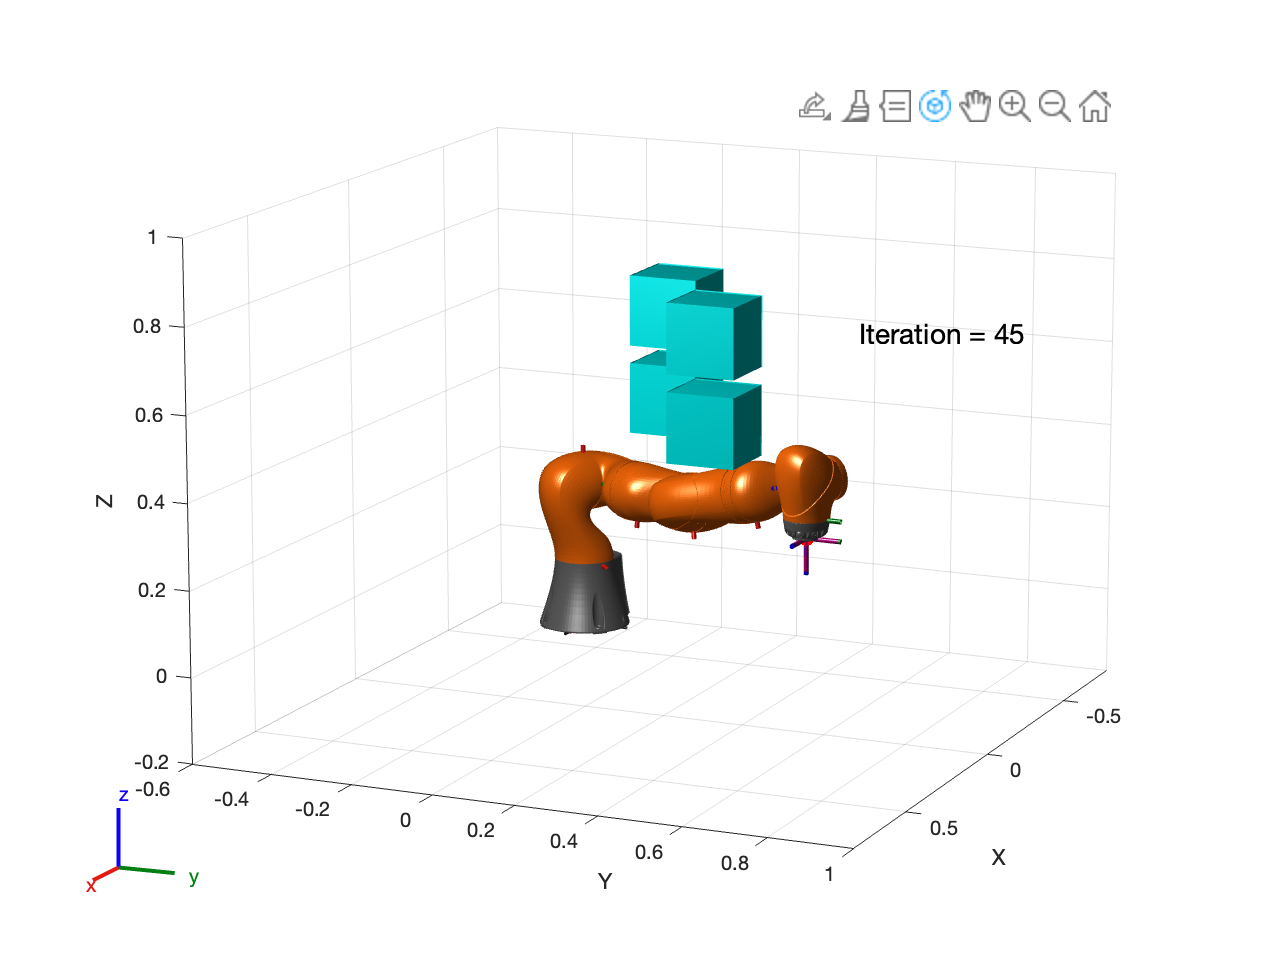

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.